# Call and Provide ROS Services

ROS supports three main communication mechanisms: topics, services, and actions. Today we will focus on the second type: Services.

From before, we learned about topics/publishers/subscribers as a many-many communication protocal and as an asynchronous protocol. 

*Services*, on the other hand, implement a tighter coupling by allowing **request-response** communication. 

- A *service client* sends a request message to a *service server* and waits for a response. 

- The server will use the data in the request to construct a response message and sends it back to the client. 

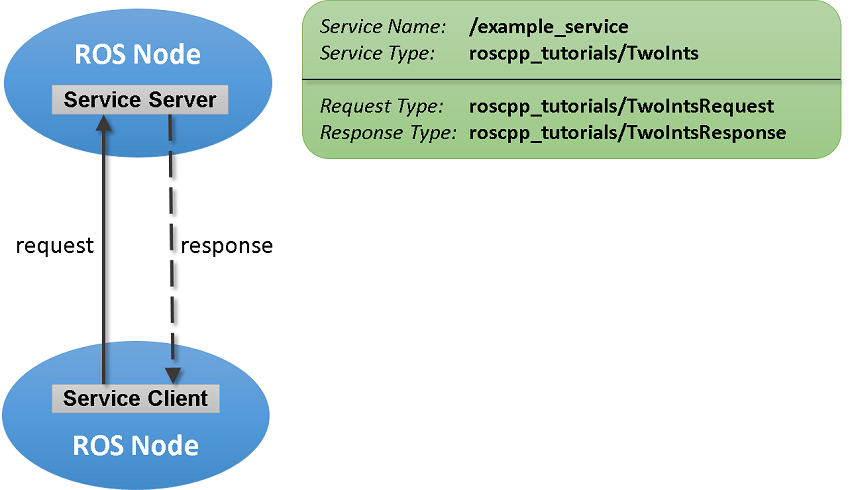

Each service has a **type** that determines the **structure** of the request and response messages. 

Services also have a **name** (a service topic) that is unique in the ROS network.

This service communication has the following characteristics:

- A service request (or service call) is used for one-to-one communication. A single node will house the service client and initiate a request that only the service server (housed in a different node) will receive and process before sending back a response.

- A **service client** and a **service server** are tightly coupled when a* service call* is executed. The server needs to exist at the time of the service call and once the request is sent, the client will block until a response is received.

This live notebook shows you how to:

- Create a callback function that will tell the server what to do

- Create service servers via `ros.ServiceServers` (or `rossvcserver` ) to advertise a service to the ROS network. 

- Create service messages via the `rosmessage` function

- Create service clients via `ros.ServiceClient` (or rossvcclient) to issue requests to the server.

- Initiate the service call

- Find information about services in the network via the `rosservice` helper method.

In its simplest form, code to create a service server/client/call might look as follows:

server = rossvcserver('/test', 'std_srvs/Empty', @exampleHelperROSEmptyCallback, 'DataFormat', 'struct')
client = rossvcclient('/test','DataFormat','struct');
req = rosmessage(client)
call(client,req)

Do not yet run this code, but let's flesh out more of the details and possibilities.

## 01 Toy Example

### A. Create Service Server

### rosservice list

Earlier we learned to loook at special ros helper methods like rosnodes or rostopic:

rosnode list

rostopic list

Services have a similar helper method `rosservice`:

rosservice list

rosservice info /test
rosservice type /test

#### Service Servers

We are now ready to explore service servers. 

Suppose you want to make a simple service server that displays the following message when the client calls:

        `-------------------------------------------------------------------`

        `Service Server is running.`

        `ROS Service client issued a call`

        `Would normally process input resp and produce a useful output again in resp`

        `-------------------------------------------------------------------`

To this end, 

- Create the service server using the ros.ServiceServer (or [`rossvcserver`](docid:ros_ref.bupf5_j_11)`)` command. You will need to specify a few things:

- Specify the host node (if using `rossvcserver` it is automatically attributed to the global node)

- Specify the service topic

- Specificy the service message type (this message will be the generic type with no Request or Response appended at the end).

- Specify a "**callback function**" which will specify the behavior of the server. Callbacks will take a function handle @. The function will be defined in a separate .m file. This function will require the following declaration style: 

`        function`` response = serviceCallback(src,reqMsg,defaultRespMsg)`

- Specify a structure data format.

For faster performance, use services with messages in structure format.

Let's create two nodes: a client and a server node:

client_node = ros.Node('client_node');
server_node = ros.Node('server_node');

Now, let's create the service server on topic **/test** and use the base service message type: **std_srvs/Empty** (there will be a request and response equivalent of them):

test_server = ros.ServiceServer(server_node, ...                         % Server node

Node: /server_node
URI: rosrpc://o-eng-5926-w:56075
Type: std_srvs/Empty
Args: MessageType


                                "/test", ...                             % Service Topic
                                "std_srvs/Empty", ...                    % Service msg type
                                @exampleHelperROSEmptyCallback, ...      % Callback 
                                "DataFormat","struct")                   % Structure

If we used `rossvcserver` the same call would look as shown below. Only call one, not both.

test_server = rossvcserver("/test", ...                                 % Service Topic

test_req = struct with fields:
    MessageType: 'std_srvs/EmptyRequest'


                           "std_srvs/Empty", ...                        % Base Service msg type
                           @exampleHelperROSEmptyCallback, ...          % Callback 
                           "DataFormat","struct")                       % Structure

test_resp = struct with fields:
    MessageType: 'std_srvs/EmptyResponse'


After creating the rosservice server object, you can identify this service by its service topic `/test` when you list all services in the ROS network.

rosservice list

You can get more information about your service using [`rosservice`](docid:ros_ref.bupf5_j_7)` info`. The global node is listed as node where the service server is reachable and you also see its `std_srvs/Empty` service type. 

rosservice info /test

### B. Callback Function

Let's take some time to analyze the callback function. 

The callback function will be an independent m file with a declaration of the following type:

`    resp = ``callback_function_name``(~,req,resp) `

This is how callbacks work:

- Call back functions get automatically called anytime a client makes a request via the `call` method 

- The request message gets copied into req (currently empty). 

- The response occurs into places: (i) resp as an input (even though it is designed to be an output). You need to here to set the resp to whatever manipulation you do of req; (ii) output of the function (i.e. resp = callback_function_name). 

- The client then receives the output answer and sets it equal to its output variable. 

- The output variable can then be used to do further operations.

Let's take a look at a toy callback:

exampleHelperROSEmptyCallback

### C. Creating a ROS Service Client

Use service clients to request information from a ROS service server. 

To create a client object, use ros.ServiceClient (or [`rossvcclient`](docid:ros_ref.bupf5_j_10)`)` call that takes:

- node name

- a service topic name and

- a struct data format

Let's create a service client for the `/test` service that we just created.

test_client = ros.ServiceClient(client_node, ...          % Client node
                                "/test", ...              % Service topic
                                "DataFormat","struct")    % Structure

Or, if we used the `rossvcclient` call, use the format below. Do not call both.

test_client = rossvcclient("/test", ...                 % Service topic
                           "DataFormat","struct")       % Structure

Note: `rossvcclient` can also be used instead of `ros.ServiceClient`

### D. ROS Service Messages

Let's confirm the message type of our service topic

rosservice info /test

ans = struct with fields:
    MessageType: 'roscpp_tutorials/TwoIntsRequest'
              A: 0
              B: 0


Note the service message is of the base type: `std_srvs/Empty`.

Now, if you use <tab> to extend the type of `std_srvs/Empty `you will find its 2 alternatives:

So how does it all work?

Service base messages types will always have their **request** and **response** alternatives.

In python/C++ this would be the same message, but in Matlab, it is broken down into two separate messages. 

#### A. Generic Interface message

The ***request*** message can be created by using rosmessage with the ***client*** object.

test_req = rosmessage(test_client)          % Create your test request message

int64 A
int64 B



The ***response*** message can be created by using rosmessage with the ***server*** object. 

test_resp = rosmessage(test_server)          % Create your test request message

ans = struct with fields:
    MessageType: 'roscpp_tutorials/TwoIntsResponse'
            Sum: 0


In this 'Empty' type of message, the internal stuctures do not vary. But in the next example they will. So keep in mind this difference.

### E. Having the Client Call the Server

In the next section, we will make our first call from the client to the server. 

In its simplest form, the call includes:

- The service client object

- The service message

- And an output variable to collect the response.

 test_resp = call(test_client, test_req)  

### F. Checking Connectivity

If we want to be more careful about checking that the connection is established. then there are two general steps we need to follow:

- Confirm the service server *exists* (do not assume it exists, things can fail to start/crash or plain forget to launch it!)

- Try to *make a connection* to the server

- Only when the connection exists, *make the call*

01 Confirm the Service Server exists via `waitForServer.`

`waitForServer `takes 2 input arguments: 

- Service Client Object

- A tuple 'Name', 'Value' to establish the timeout time.

If the service server exists, waitforServer exits without error. If it does not exist it will send out an exception (or error) saying that the /test service was not available.

waitForServer(test_client,"Timeout",3) % todo: this is best done inside a try-catch block to catch exceptions. 

sum_server =   ServiceServer with properties:

      ServiceType: 'roscpp_tutorials/TwoInts'
      ServiceName: '/sum'
    NewRequestFcn: @exampleHelperROSSumCallback
       DataFormat: 'struct'


Once we confirm the existence of the server, we use the [`call`](docid:ros_ref.buqbgqj) function to call the service server which will return a response. In this case, we will explore a more sophisticated way of collecting outputs from `call` including status messages. 

Pay attention to the following points:

- The test service server you created earlier will return an empty response. 

- Place a break point inside the `exampleHelperROSEmptyCallback` callback to see how it gets called when we issue the `call` method. That callback will display the string *"A service client is calling", *which will show in your command window. 

- As with waitForServer, it is possible to set a `Timeout` parameter to ensure that we receive a timely response. Otherwise a fix needs to be in place.

[sum_resp,status,status_text]  = call(test_client, ...   % Client object has access to the service topic

sum_client =   ServiceClient with properties:

     ServiceType: 'roscpp_tutorials/TwoInts'
     ServiceName: '/sum'
    IsPersistent: 1
      DataFormat: 'struct'


                                  test_req, ...      % Service message, currently empty
                                  "Timeout",3)       % Timeout

`call` issues 3 outputs:

- `test_resp:`     contains the output of the server and would be used to then further do something in your code.

- `status`:            true or false indicates success or faillure

- `status_text: string indicating state of service server... i.e. what kind of failure might have ocurred`

### Handling Broken Connections

Let's consider a case where the Service Server does not exist or has failed for some reason. 

Delete your service server object:

clear test_server

sum_req = struct with fields:
    MessageType: 'roscpp_tutorials/TwoIntsRequest'
              A: 0
              B: 0


Let's issue the waitForServer call once again:

waitForServer(test_client,"Timeout",3)

What happens after the timeout?

#### Try-Catch Block

We do not want our code to fail. Otherwise it crashes and prevents further execution. 

A way to handle errors in programming is through what is called a `'try-catch'` block. 

You put the code you want to test inside the try block, if it fails, you do whatever is in the catch. 

Inside the try block we call `waitForServer` to check if we can connect to the server. 

If that fails, display a warning message and perhaps re-start the test_server, or choose another operation...

try
    waitForServer(test_client,"Timeout",3)
    disp('Successfully connected to the service server...')
catch
    disp('No service server running. Try running again...')
    test_server = ros.ServiceServer(node,"/test","std_srvs/Empty",@exampleHelperROSEmptyCallback,"DataFormat","struct") 
end

Similarly, another round of checks can happen when we call the server from the client. 

We can again use a try-catch block or alternatively use the status output of call and use that to inform a decision. 

See this example:

numCallFailures = 0;
[sum_resp,status,statustext] = call(test_client, test_req, "Timeout",3);

% Use conditional statements to proceed

% Failure
if ~status % I.e. failure (when call fails, status = 0. ~0 is the same as true. So, we enter this section upon failure.

Successfully connected to the service server...



    numCallFailures = numCallFailures + 1;
    fprintf("Call failure number %d. Error cause: %s\n", numCallFailures, statustext)

% Success
else
    % Display the output of your server via resp
    disp(sum_resp) % We use display here since we know the server only produces a string output. 
end

## 02 Create a Service for Adding Two Numbers

Start by resetting variables:

clear

    MessageType: 'roscpp_tutorials/TwoIntsResponse'
            Sum: 173



Let's try something simple: a service server that adds two numbers a & b and returns a sum. Inputs a & b will be encoded in an existing structure called `roscpp_tutorials/TwoIntsRequest`. The answer will go onto a separate message type `roscpp_tutorials/TwoIntsResponse.`

In its simplest form, 7 lines of code would create a server, create a client, populate the message, call the client, and then receive the response:

sum_server  = rossvcserver("/sum","roscpp_tutorials/TwoInts",@exampleHelperROSSumCallback,"DataFormat","struct")

/camera/set_camera_info
/camera/set_parameters
/controller_manager/list_controller_types
/controller_manager/list_controllers
/controller_manager/load_controller
/controller_manager/reload_controller_libraries
/controller_manager/switch_controller
/controller_manager/unload_controller
/gazebo/apply_body_wrench
/gazebo/apply_joint_effort
/gazebo/clear_body_wrenches
/gazebo/clear_joint_forces
/gazebo/delete_light
/gazebo/delete_model
/gazebo/get_joint_properties
/gazebo/get_light_properties
/gazebo/get_link_properties
/gazebo/get_link_state
/gazebo/get_loggers
/gazebo/get_model_properties
/gazebo/get_model_state
/gazebo/get_physics_properties
/gazebo/get_world_properties
/gazebo/pause_physics
/gazebo/reset_simulation
/gazebo/reset_world
/gazebo/set_joint_properties
/gazebo/set_light_properties
/gazebo/set_link_properties
/gazebo/set_link_state
/gazebo/set_logger_level
/gazebo/set_model_configuration
/gazebo/set_model_state
/gazebo/set_parameters
/gazebo/set_physics_properties
/gazebo/spa

sum_client  = rossvcclient("/sum","DataFormat","struct")

sum_req     = rosmessage(sum_client);
sum_resp    = rosmessage(sum_server);

sum_req.A   = int64(2);
sum_req.B   = int64(1)

sum_resp    = call(sum_client,sum_req,"Timeout",3)

Let's break it down step-by-step:

### A. Understanding the Service Request and Response Message

In this example, we make use of the service base message: `roscpp_tutorials/TwoInts`

#### Request Service Message

The request version of the base type will be: `roscpp_tutorials/TwoIntsRequest `that contains 2 integers, `A` and `B and will be used as inputs to the server.`

Examine via  rosmessage:

rosmessage('roscpp_tutorials/TwoIntsRequest', 'DataFormat','struct')

gazebo_msgs/SetModelState


Or the `rosmsg show `helper call:

rosmsg show roscpp_tutorials/TwoIntsRequest

msg = struct with fields:
    MessageType: 'gazebo_msgs/SetModelStateRequest'
     ModelState: [1×1 struct]


Important:

Notice the type here. It's not a double, it's an int64. When you create your message, you will need to ***cast*** your variable value to an int64. 

#### Response Service Message

The response version of the base type will be: `roscpp_tutorials/TwoIntsResopnse `contains a Sum field where the output should be placed within the callback function:

Examine via  rosmessage:

rosmessage('roscpp_tutorials/TwoIntsResponse', 'DataFormat','struct')

ans = struct with fields:
       MessageType: 'gazebo_msgs/ModelState'
         ModelName: ''
              Pose: [1×1 struct]
             Twist: [1×1 struct]
    ReferenceFrame: ''


Before we actually create the official service message, let's creat a service server and service client first. Their types will help us more robustly create the type for the message later on.

### B. Create the Service Server

As before, to create the service server, we need a service topic, a service message type, a callback, and the data format. 

*Importantly, we will need a callback that takes a handle with two inputs and adds them up together. *

`Let's examine the callback (do Ctrl+D on the script):`

exampleHelperROSSumCallback

Let's create a service server with `rossvcserver` (no need to assign a node in this method):

sum_server = rossvcserver("/sum", ...                        % Service topic

set_model_req = struct with fields:
    MessageType: 'gazebo_msgs/SetModelStateRequest'
     ModelState: [1×1 struct]


                         "roscpp_tutorials/TwoInts", ...    % Base Service message type
                         @exampleHelperROSSumCallback, ...  % Callback script
                         "DataFormat","struct")             % Structure

### C. Create the Service Client

Asb before, to create a service client, just provide the service topic:

sum_client = rossvcclient("/sum","DataFormat","struct")

set_model_req = struct with fields:
    MessageType: 'gazebo_msgs/SetModelStateRequest'
     ModelState: [1×1 struct]


#### E. Creating the Service Message

We are now ready to create the message. This is best implemented by passing the `service client object` as the type:

sum_req = rosmessage(sum_client)

set_model_req = struct with fields:
    MessageType: 'gazebo_msgs/SetModelStateRequest'
     ModelState: [1×1 struct]


Now we can set the fields A and B of sumreq. I will randomly select an integer between 1 and 100 and cast it as an int64:

sum_req.A = int64( randi(100) );         % Need to convert from double to int64

set_model_req = struct with fields:
    MessageType: 'gazebo_msgs/SetModelStateRequest'
     ModelState: [1×1 struct]


sum_req.B = int64( randi(100) );         % randi samples random integers between 1 and 100 from a uniform distribution

Note:

We have not cretead a resopnse yet. When the client call's the ServiceServer matlab automatically assigns the correct type to the ouput. I will bring this up later when it comes up.

### E. Client Calls Server

Now, we can call the Service Server and add the two input numbers. 

We will: (i) ensure the connection and then (ii) make the call:

Check connection:

try

set_model_resp = struct with fields:
      MessageType: 'gazebo_msgs/SetModelStateResponse'
          Success: 1
    StatusMessage: 'SetModelState: set model state done'


status = logical
   1


statustext = 'success'

    waitForServer(sum_client,"Timeout",3);
    disp('Successfully connected to the service server...');
catch
    disp('No service server running. Try running again...');
    sum_server = ros.rossvcserver("/sum", "roscpp_tutorials/TwoInts", @exampleHelperROSSumCallback,"DataFormat","struct");
end

Call the client:


numCallFailures = 0;

reset_client =   ServiceClient with properties:

     ServiceType: 'std_srvs/Empty'
     ServiceName: '/gazebo/reset_world'
    IsPersistent: 1
      DataFormat: 'struct'


[sum_resp,status,statustext] = call(sum_client, sum_req, "Timeout",3);

reset_req = struct with fields:
    MessageType: 'std_srvs/EmptyRequest'


reset_resp = struct with fields:
    MessageType: 'std_srvs/EmptyResponse'


status = logical
   1


statustext = 'success'

% Use conditional statements to proceed
% Failure
if ~status % I.e. failure (when call fails, status = 0. ~0 is the same as true. So, we enter this section upon failure.

    numCallFailures = numCallFailures + 1;

unpausePhys_resp = struct with fields:
    MessageType: 'std_srvs/EmptyResponse'


status = logical
   1


statustext = 'success'

    fprintf("Call failure number %d. Error cause: %s\n", numCallFailures, statustext)

% Success
else
    % Display the output of your server via resp

set_phys_req = struct with fields:
      MessageType: 'gazebo_msgs/SetPhysicsPropertiesRequest'
         TimeStep: 0
    MaxUpdateRate: 0
          Gravity: [1×1 struct]
        OdeConfig: [1×1 struct]


    disp(sum_resp) % We use display here since we know the server only produces a string output. 
end

## Shut Down ROS Network

Clear data

clear

ans = struct with fields:
    MessageType: 'geometry_msgs/Vector3'
              X: 0
              Y: 0
              Z: 0


Shut down the ROS master and delete the global node.

rosshutdown

set_phys_req = struct with fields:
      MessageType: 'gazebo_msgs/SetPhysicsPropertiesRequest'
         TimeStep: 0
    MaxUpdateRate: 0
          Gravity: [1×1 struct]
        OdeConfig: [1×1 struct]


## 03 Interacting with Gazebo

we will be interacting with the Gazebo simulation. 

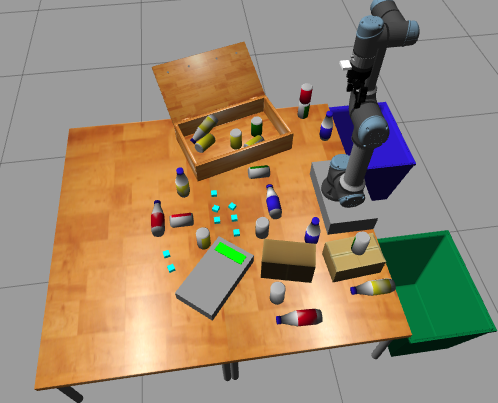

To this end, you will need to run your virtual machine and start the armgazebo container. 

Remember to call run.bash from inside src/arm_gazebo/docker:

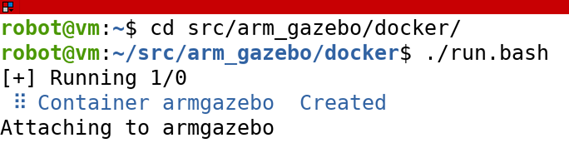

Also retrieve your hostname via command: hostname -I

#### Connect MATLAB to Gazebo using the ROS Toolbox

Note: for connections inside Lipscomb's network make sure you have already updated your hosts files by setting the IP address above followed by VM.

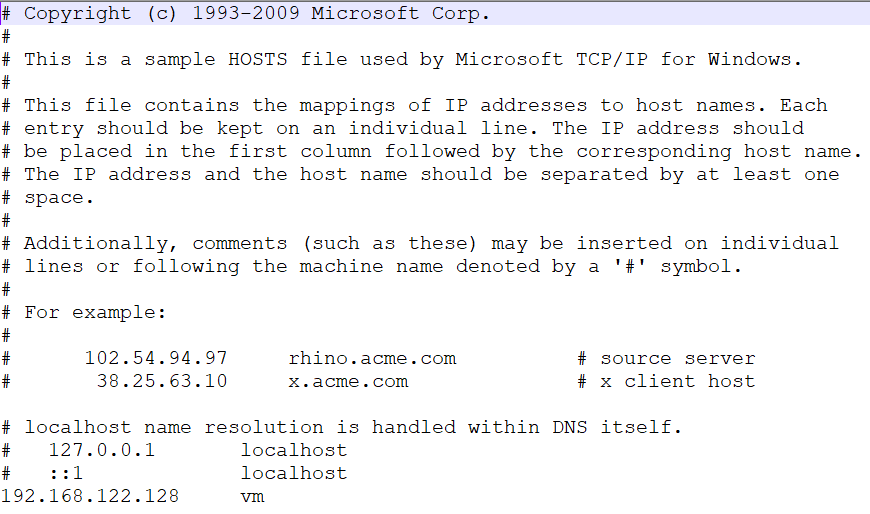

Once, you have done that, you can simply call rosinit with the IP address of your virtual machine:

rosinit('192.168.122.128');

set_model_resp = struct with fields:
      MessageType: 'gazebo_msgs/SetPhysicsPropertiesResponse'
          Success: 1
    StatusMessage: 'physics engine updated'


status = logical
   1


statustext = 'success'

### Gazebo Services

The gazebo simulator has many services that it offers. Let's see what they are:

rosservice list

For the purposes of this notebook section, we will only explore a few. But you are encouraged to research the others. 

In particular, we we ill look at:

- /gazebo/set_model_state

- /gazebo/reset_world 

- /gazebo/unpause_physics

#### A. Gazebo Service: Set Model State

Any object that exists in Gazebo is considered a model. 

Models have properties like name: positions, velocities, etc. 

We can discover these by looking at the message type of the service topic. 

Note that we will have a structure of structures:

- the top structure will be of type `gazebo_msgs/SetModelState`.

- Inside of that there will be a `gazebo_msgs/ModelState`. This last one captures their names, positions, etc.

Let's start by pulling the base type of the service topic:

rosservice type /gazebo/set_model_state

This base type will have a Request and Response alternatives `(which includes gazebo_msgs/SetModelStateRequest and gazebo_msgs/SetModelStateResponse).`

Let's look at the request version via `rosmessage`:

msg = rosmessage('gazebo_msgs/SetModelStateRequest', 'DataFormat','struct')

Here we have a new structure inside. Let's look at that one:

msg.ModelState % or rosmessage('gazebo_msgs/ModelState', 'DataFormat','struct')

Note that ModelState now reveals it has 4 fields:

- ModelName (string): will be the name of the model (i.e. an object) 

- a Pose (position and orientation)

- a Twist (linear velocity and angular velocity), and

- a Reference frame.

Note that you can see a list of all the models in the side pane of Gazebo:

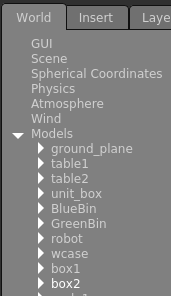

You can also click on any model in Gazebo to reveal its properties:

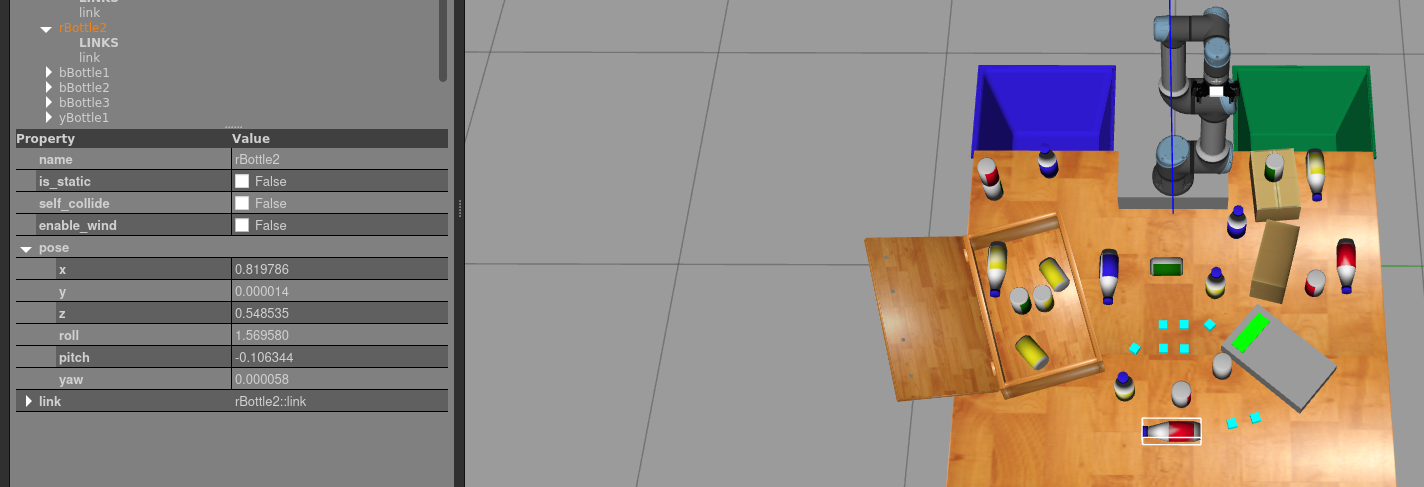

In essence, filling up this message is equivalent to saying that you want to move an object to a different location/orientation or give it a velocity!

In this case, we do not need to create a service server. It has already been created by the gazebo simulator.

Here, we only need to create the client:

gazebo_model_client = rossvcclient('/gazebo/set_model_state', 'DataFormat', 'struct')

set_model_resp = struct with fields:
      MessageType: 'gazebo_msgs/SetModelStateResponse'
          Success: 1
    StatusMessage: 'SetModelState: set model state done'


status = logical
   1


statustext = 'success'

Note: it may take several seconds to create due to the delay with the VM.

#### Create the Request message

We can create the request message `set_model_req` directly from the `gazebo_model_client` object:

set_model_req = rosmessage(gazebo_model_client) 

### Populate the Message

As noted earlier, the message has lots of information on it. 

Fortunately you do not have to fill it all out. Imagine you want to take the red bottle I highlighted earlier and change its pose. 

In this case, set the model name and then the Pose field:

set_model_req.ModelState.ModelName = 'rBottle2'
set_model_req.ModelState.Pose.Position.X = 0.9
set_model_req.ModelState.Pose.Position.Z = 0.6

#### Call the Client

For this section, let's do simple client calls, to facilitate the process. As you get ready to call the client, this will be the first time that you see the service do something interesting. 

Before you run the following code, make sure you can see your simulation from a top-down view from where the red bottle 2 is clearly seen:

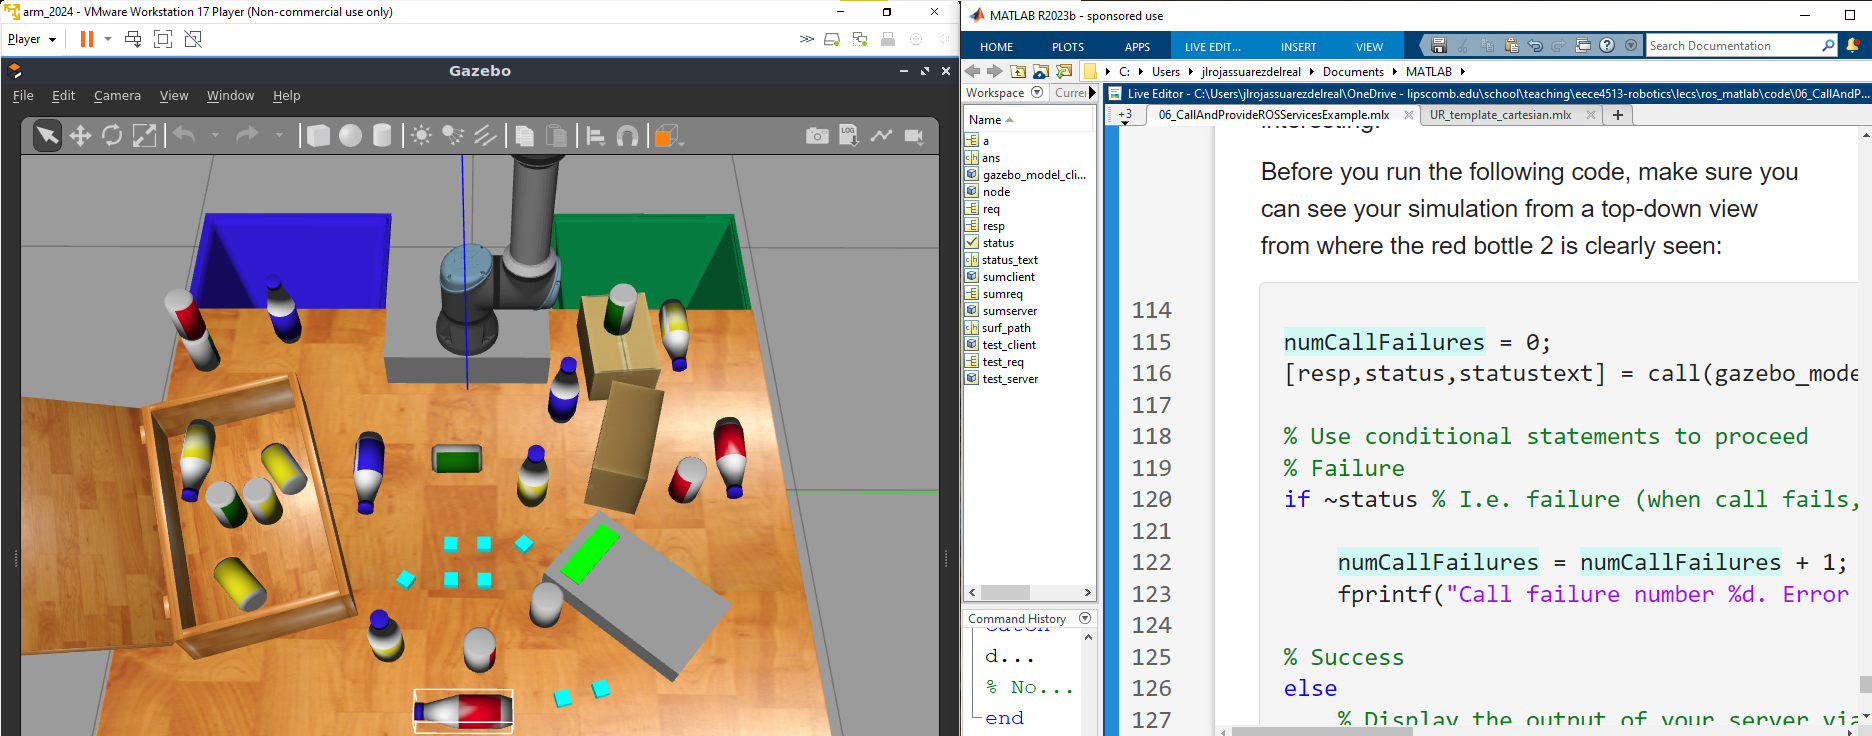

[set_model_resp,status,statustext] = call(gazebo_model_client, set_model_req)

Now that you have seen how the manually set position affected the actual object, take some time to change its position, orientation, even linear velocity, or angular velocity. 

Note, velocity is more tricky as the objects have friction with their surfaces and the call only applies the velocity during an infinitesimmaly short amount of time.

### B. Gazebo Service: Reset World 

The reset wor

Create a client, a message (which will be empty). When you call see the effects in the simulator::

reset_client = rossvcclient('/gazebo/reset_world', 'DataFormat','struct')
reset_req = rosmessage(reset_client) % type is std_srvs/EmptyRequest... so we can call without populating
[reset_resp,status,statustext]=call(reset_client,reset_req)

### C. Gazebo Service: Unpause physics

unpausePhys_client = rossvcclient('/gazebo/unpause_physics', 'DataFormat', 'struct');
unpausePhys_req = rosmessage(unpausePhys_client);
[unpausePhys_resp, status, statustext] = call(unpausePhys_client,unpausePhys_req)

### D. Gazebo Service: Set Physics Properties (Gravity)

set_phys_client = rossvcclient('/gazebo/set_physics_properties', 'DataFormat', 'struct');
set_phys_req = rosmessage(set_phys_client)

Check out the physmsg structure which has a gravity field inside:

set_phys_req.Gravity % currently gravity is set to 0 in all directions. 

Set the gravity to zero:

set_phys_req.Gravity.Z = 0
[set_model_resp,status,statustext] = call(set_phys_client, set_phys_req)

Now reload an object in the air. It does not fall anymore.

% gazebo_model_client = rossvcclient('/gazebo/set_model_state', 'DataFormat', 'struct');
% set_model_req.ModelState.ModelName = 'rBottle2';
% set_model_req.ModelState.Pose.Position.X = 0.9;
% set_model_req.ModelState.Pose.Position.Z = 0.8;
[set_model_resp,status,statustext] = call(gazebo_model_client, set_model_req)

## Shut Down ROS Network

Remove the sample nodes and service servers from the ROS network.

exampleHelperROSShutDownSampleNetwork

Shut down the ROS master and delete the global node.

rosshutdown

*Copyright 2014-2021 The MathWorks, Inc.*